clear all;
close all;

%Initial Conditions
V = 644; % Reactor volume (L)
rho = 1; % Density (kg/L)
F_i = 3; % Input flow rate (kg/min)
F_o = 2.3;% Output flow rate (kg/min)
F_v = F_i - F_o; % Vapor flow rate (kg/min)
T = 280; %Temperature in C

% Kinetic parameters
k1 = 4.0e4 * exp(-15.0e3 / (1.987 * (T + 273.15))) / 60;
k2 = 2.0e4 * exp(-15.0e3 / (1.987 * (T + 273.15))) / 60;
k3 = 6.8e5 * exp(-18.5e3 / (1.987 * (T + 273.15))) / 60 * 10;
k4 = 4.16e7 * exp(-29.8e3 / (1.987 * (T + 273.15))) / 60;
k5 = 4.16e7 * exp(-29.8e3 / (1.987 * (T + 273.15))) / 60;
k6 = k5;
k7 = 1.04e6 * exp(-17.6e3 / (1.987 * (T + 273.15))) / 60;
k8 = k7;
k9 = 3.6e8 * exp(-37.8e3 / (1.987 * (T + 273.15))) / 60 * 2;

% Equilibrium constants
K1 = 0.3;
K2 = 0.15;
K3 = 0.5;
K7 = 2.5;
K8 = 1.25;

% Initial concentrations
e_g0 = 7.87;
z0 = 3.935;
g0 = 0.007098;
e_c0 = 0.1;
w0 = 0.000000104;
e_m0 = 0;
e_v0 = 0;
bhet0 = z0;
pet0 = 0.0000044;
eg_removed0 = 0;

% Input concentrations
e_gi = e_g0;
z_i = z0;
g_i = g0;
e_ci = e_c0;
w_i = w0;
e_mi = e_m0;
bhet_i = bhet0;
pet_i = pet0;

% Time span
tspan = [0 120];

% Initial conditions vector
y0 = [e_g0, z0, g0, e_c0, w0, e_m0, e_v0, bhet0, pet0, eg_removed0];

% ODE solver
options = odeset('RelTol', 1e-4, 'AbsTol', 1e-6);
[t, y] = ode15s(@(t, y) cstr_dynamics(t, y, F_i, F_o, F_v, V, rho, k1, k2, k3, k4, k5, k6, k7, k8, k9, ...
    K1, K2, K3, K7, K8, e_gi, z_i, g_i, e_ci, w_i, e_mi, bhet_i, pet_i), tspan, y0, options);

% Extract concentrations
e_g = y(:, 1);
z = y(:, 2);
g = y(:, 3);
e_c = y(:, 4);
w = y(:, 5);
e_m = y(:, 6);
e_v = y(:, 7);
bhet = y(:, 8);
pet = y(:, 9);
eg_removed = y(:, 10);

% Calculate DP
total_units = z0;
DP = (pet + bhet) ./ (e_g / 2 + e_c + e_v + e_m);

% Calculate final output flow rates and rates of change
e_g_out = F_o * e_g(end);
z_out = F_o * z(end);
g_out_liquid = F_o * g(end);
e_c_out = F_o * e_c(end);
w_out_liquid = F_o * w(end);
e_m_out = F_o * e_m(end);
e_v_out = F_o * e_v(end);
bhet_out = F_o * bhet(end);
pet_out = F_o * pet(end);
R3_final = k3 * (e_g(end)^2 - 4 * pet(end) * g(end) / K3);
eg_removal_rate_final = F_v * g(end) + rho * V * max(R3_final, 0);
g_out_vapor = eg_removal_rate_final;
w_out_vapor = F_v * w(end);

% Compute final dy/dt to check steady state
dydt_final = cstr_dynamics(t(end), y(end, :)', F_i, F_o, F_v, V, rho, k1, k2, k3, k4, k5, k6, k7, k8, k9, ...
    K1, K2, K3, K7, K8, e_gi, z_i, g_i, e_ci, w_i, e_mi, bhet_i, pet_i);

% Final concentrations, output flow rates, and dy/dt
fprintf('Final Concentrations at t = %.1f minutes:\n', t(end));

Final Concentrations at t = 120.0 minutes:


fprintf('Hydroxyl End Groups (e_g): %.4f mol/kg, Output Flow Rate: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', e_g(end), e_g_out, dydt_final(1));

Hydroxyl End Groups (e_g): 1.7431 mol/kg, Output Flow Rate: 4.01 mol/min, dy/dt: -4.52e-04 mol/kg·min


fprintf('Diester Groups (z): %.4f mol/kg, Output Flow Rate: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', z(end), z_out, dydt_final(2));

Diester Groups (z): 7.8454 mol/kg, Output Flow Rate: 18.04 mol/min, dy/dt: 5.81e-03 mol/kg·min


fprintf('Ethylene Glycol (g): %.4f mol/kg, Liquid Output: %.2f mol/min, Vapor Output: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', g(end), g_out_liquid, g_out_vapor, dydt_final(3));

Ethylene Glycol (g): 0.0097 mol/kg, Liquid Output: 0.02 mol/min, Vapor Output: 9.90 mol/min, dy/dt: 1.43e-05 mol/kg·min


fprintf('Acid End Groups (e_c): %.4f mol/kg, Output Flow Rate: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', e_c(end), e_c_out, dydt_final(4));

Acid End Groups (e_c): 0.1141 mol/kg, Output Flow Rate: 0.26 mol/min, dy/dt: 8.83e-05 mol/kg·min


fprintf('Water (w): %.4f mol/kg, Liquid Output: %.2f mol/min, Vapor Output: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', w(end), w_out_liquid, w_out_vapor, dydt_final(5));

Water (w): 0.0229 mol/kg, Liquid Output: 0.05 mol/min, Vapor Output: 0.02 mol/min, dy/dt: 3.07e-06 mol/kg·min


fprintf('Methyl End Groups (e_m): %.4f mol/kg, Output Flow Rate: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', e_m(end), e_m_out, dydt_final(6));

Methyl End Groups (e_m): 0.0000 mol/kg, Output Flow Rate: 0.00 mol/min, dy/dt: 0.00e+00 mol/kg·min


fprintf('Vinyl End Groups (e_v): %.4f mol/kg, Output Flow Rate: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', e_v(end), e_v_out, dydt_final(7));

Vinyl End Groups (e_v): 0.0000 mol/kg, Output Flow Rate: 0.00 mol/min, dy/dt: 3.39e-08 mol/kg·min


fprintf('BHET: %.4f mol/kg, Output Flow Rate: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', bhet(end), bhet_out, dydt_final(8));

BHET: 0.8874 mol/kg, Output Flow Rate: 2.04 mol/min, dy/dt: -1.98e-04 mol/kg·min


fprintf('PET (repeating units): %.4f mol/kg, Output Flow Rate: %.2f mol/min, dy/dt: %.2e mol/kg·min\n', pet(end), pet_out, dydt_final(9));

PET (repeating units): 3.4929 mol/kg, Output Flow Rate: 8.03 mol/min, dy/dt: 3.02e-03 mol/kg·min


fprintf('Degree of Polymerization (DP): %.2f\n', DP(end));

Degree of Polymerization (DP): 4.44


fprintf('Total Ethylene Glycol Removed: %.2f mol\n', eg_removed(end));

Total Ethylene Glycol Removed: 3040.24 mol


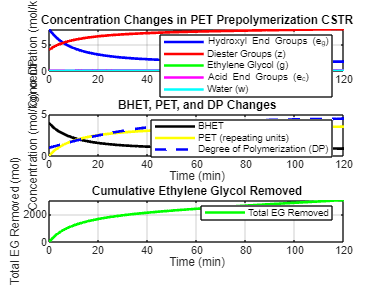


% Plotting
figure;
subplot(3, 1, 1);
plot(t, e_g, 'b-', 'LineWidth', 2, 'DisplayName', 'Hydroxyl End Groups (e_g)');
hold on;
plot(t, z, 'r-', 'LineWidth', 2, 'DisplayName', 'Diester Groups (z)');
plot(t, g, 'g-', 'LineWidth', 2, 'DisplayName', 'Ethylene Glycol (g)');
plot(t, e_c, 'm-', 'LineWidth', 2, 'DisplayName', 'Acid End Groups (e_c)');
plot(t, w, 'c-', 'LineWidth', 2, 'DisplayName', 'Water (w)');
xlabel('Time (min)');
ylabel('Concentration (mol/kg)');
title('Concentration Changes in PET Prepolymerization CSTR');
legend('show');
grid on;

subplot(3, 1, 2);
plot(t, bhet, 'k-', 'LineWidth', 2, 'DisplayName', 'BHET');
hold on;
plot(t, pet, 'y-', 'LineWidth', 2, 'DisplayName', 'PET (repeating units)');
plot(t, DP, 'b--', 'LineWidth', 2, 'DisplayName', 'Degree of Polymerization (DP)');
xlabel('Time (min)');
ylabel('Concentration (mol/kg) or DP');
title('BHET, PET, and DP Changes');
legend('show');
grid on;

subplot(3, 1, 3);
plot(t, eg_removed, 'g-', 'LineWidth', 2, 'DisplayName', 'Total EG Removed');
xlabel('Time (min)');
ylabel('Total EG Removed (mol)');
title('Cumulative Ethylene Glycol Removed');
legend('show');
grid on;


% ODE system
function dydt = cstr_dynamics(t, y, F_i, F_o, F_v, V, rho, k1, k2, k3, k4, k5, k6, k7, k8, k9, ...
    K1, K2, K3, K7, K8, e_gi, z_i, g_i, e_ci, w_i, e_mi, bhet_i, pet_i)
    % Extract concentrations
    e_g = y(1);
    z = y(2);
    g = y(3);
    e_c = y(4);
    w = y(5);
    e_m = y(6);
    e_v = y(7);
    bhet = y(8);
    pet = y(9);
    eg_removed = y(10);

    % Reaction rates
    R1 = k1 * (2 * e_m * g - e_g * 0 / K1);
    R2 = k2 * (e_m * e_g - 2 * z * 0 / K2);
    R3 = k3 * (e_g^2 - 4 * pet * g / K3);
    R4 = k4 * e_g;
    R5 = 2 * k5 * e_g * g;
    R6 = k6 * e_g^2;
    R7 = k7 * (2 * e_c * g - e_g * w / K7);
    R8 = k8 * (e_g * e_c - 2 * pet * w / K8);
    R9 = k9 * pet;
    R10 = k9 * e_g * e_v;

    % Enhanced EG removal
    eg_removal_rate = F_v * g + rho * V * max(R3, 0);

    % Differential equations
    de_g_dt = (F_i * e_gi - F_o * e_g + rho^2 * V * (R1 - R2 - 2 * R3 - R4 - R5 - R6 + R7 - R8 - R10)) / (rho * V);
    dz_dt = (F_i * z_i - F_o * z + rho^2 * V * (R3 + R8 - R9)) / (rho * V);
    dg_dt = (F_i * g_i - F_o * g - eg_removal_rate + rho^2 * V * (R3 - R5 - R7)) / (rho * V);
    de_c_dt = (F_i * e_ci - F_o * e_c + rho^2 * V * (R5 + R6 - R7)) / (rho * V);
    dw_dt = (F_i * w_i - F_o * w - F_v * w + rho^2 * V * (R7 + R8)) / (rho * V);
    de_m_dt = (F_i * e_mi - F_o * e_m + rho^2 * V * (-R1 - R2)) / (rho * V);
    de_v_dt = (F_i * 0 - F_o * e_v + rho^2 * V * (R9 - R10)) / (rho * V);
    dbhet_dt = (F_i * bhet_i - F_o * bhet - rho^2 * V * R3) / (rho * V);
    dpet_dt = (F_i * pet_i - F_o * pet + rho^2 * V * (R3 + R8 - R9)) / (rho * V);
    deg_removed_dt = eg_removal_rate;

    % Output vector
    dydt = [de_g_dt; dz_dt; dg_dt; de_c_dt; dw_dt; de_m_dt; de_v_dt; dbhet_dt; dpet_dt; deg_removed_dt];
end
